# Lab 3

clear; clc;

global A C W Q CtransW

I_r = 67.40;
I_p = 67.45;
I_y = 1.31;
h = 560;
a = 6378.137 + h;
n = sqrt(398600.5/a^3);

A = [0, 1; 
    -3*n^2*((I_r - I_y)/I_p), 0];
C = [1 0];
W = 1/deg2rad(5)^2;
CtransW = C'*W;

## Task 1

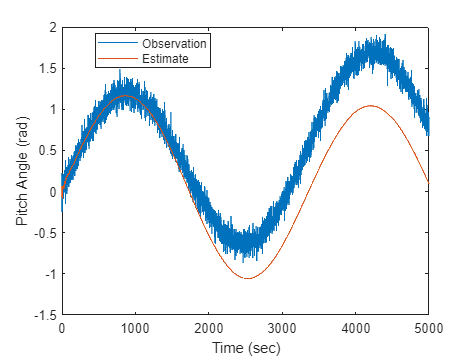

Q = zeros(2);
out_0 = runModel("5000");

figure
plot(out_0.tout, out_0.ybar, ...
    out_0.tout, reshape(out_0.yhat, [length(out_0.yhat), 1]));
ylim([-1.5 2])
xlabel("Time (sec)")
ylabel("Pitch Angle (rad)")
legend("Observation", "Estimate", "Location", "best")

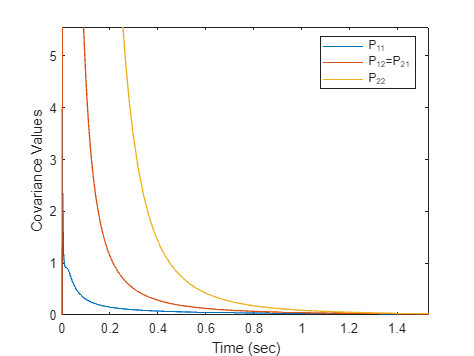


figure
plot(out_0.tout, reshape(out_0.P(1, 1, :), [length(out_0.P), 1]), ...
    out_0.tout, reshape(out_0.P(1, 2, :), [length(out_0.P), 1]), ...
    out_0.tout, reshape(out_0.P(2, 2, :), [length(out_0.P), 1]));
xlim([0 1.25])
xticks(0:0.2:2)
ylim([0 4])
xlabel("Time (sec)")
ylabel("Covariance Values")
legend("P_{11}", "P_{12}=P_{21}", "P_{22}", "Location", "best")

## Task 2

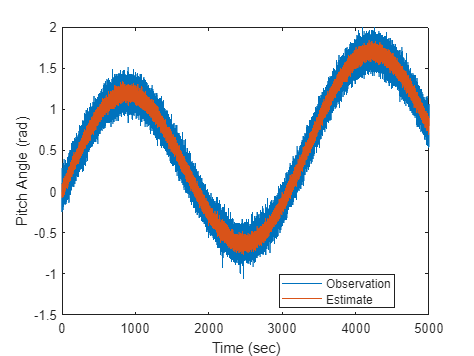

Q = eye(2);
out_1 = runModel("5000");

figure
plot(out_1.tout, out_1.ybar, ...
    out_1.tout, reshape(out_1.yhat, [length(out_1.yhat), 1]));
ylim([-1.5 2])
xlabel("Time (sec)")
ylabel("Pitch Angle (rad)")
legend("Observation", "Estimate", "Location", "best")

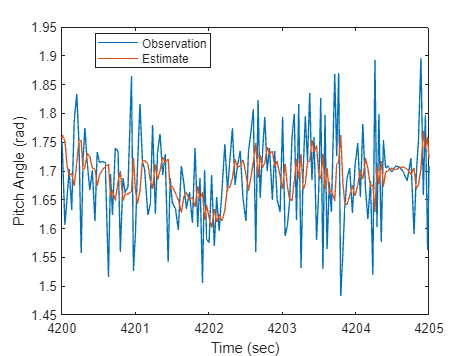


figure
plot(out_1.tout, out_1.ybar, ...
    out_1.tout, reshape(out_1.yhat, [length(out_1.yhat), 1]));
ylim([1.45 1.95])
xlim([4200 4205])
xlabel("Time (sec)")
ylabel("Pitch Angle (rad)")
legend("Observation", "Estimate", "Location", "best")

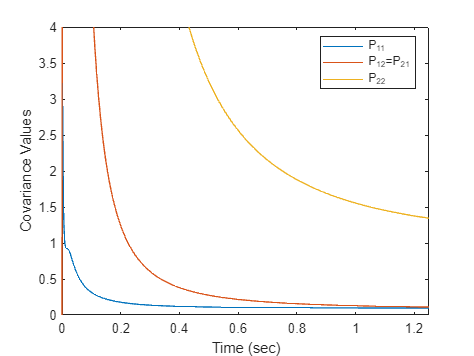


figure
plot(out_1.tout, reshape(out_1.P(1, 1, :), [length(out_1.P), 1]), ...
    out_1.tout, reshape(out_1.P(1, 2, :), [length(out_1.P), 1]), ...
    out_1.tout, reshape(out_1.P(2, 2, :), [length(out_1.P), 1]));
xlim([0 1.25])
xticks(0:0.2:2)
ylim([0 4])
xlabel("Time (sec)")
ylabel("Covariance Values")
legend("P_{11}", "P_{12}=P_{21}", "P_{22}", "Location", "best")

## Task 3

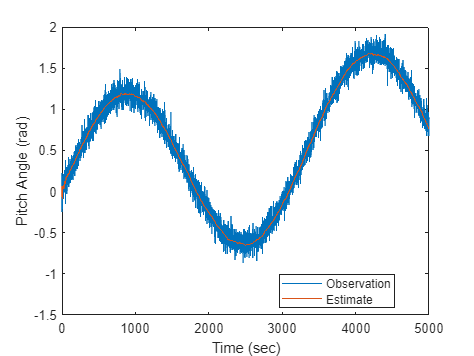

Q = eye(2)*1e-10;
out_optim = runModel("5000");

figure
plot(out_optim.tout, out_optim.ybar, ...
    out_optim.tout, reshape(out_optim.yhat, [length(out_optim.yhat), 1]));
ylim([-1.5 2])
xlabel("Time (sec)")
ylabel("Pitch Angle (rad)")
legend("Observation", "Estimate", "Location", "best")

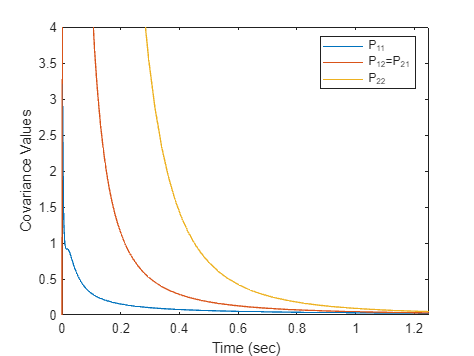


figure
plot(out_optim.tout, reshape(out_optim.P(1, 1, :), [length(out_optim.P), 1]), ...
    out_optim.tout, reshape(out_optim.P(1, 2, :), [length(out_optim.P), 1]), ...
    out_optim.tout, reshape(out_optim.P(2, 2, :), [length(out_optim.P), 1]));
xlim([0 1.25])
xticks(0:0.2:2)
ylim([0 4])
xlabel("Time (sec)")
ylabel("Covariance Values")
legend("P_{11}", "P_{12}=P_{21}", "P_{22}", "Location", "best")